# `逻辑运算`

## 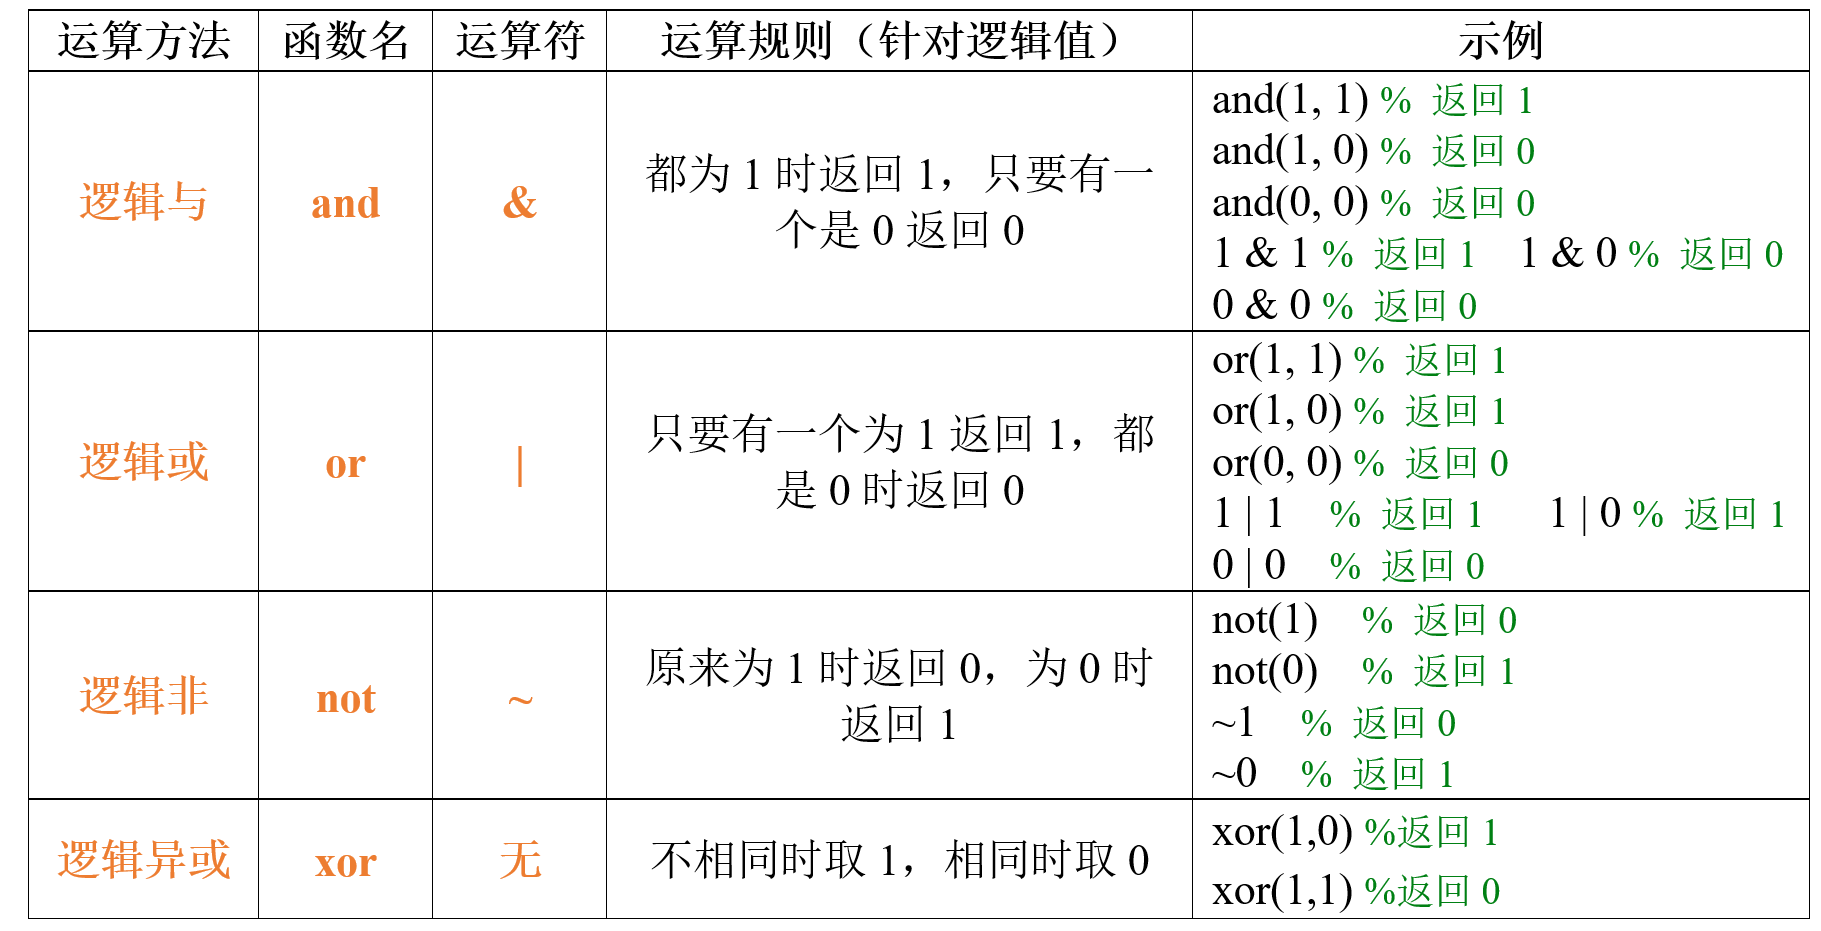

上表中函数名和对应的运算符可以执行相同的功能，除了“逻辑异或”没有相应的运算符外，剩下三个运算方法都有对应的运算符。

A = [-5 1.2  0  0  3  5.9];
B = [0   4   1  0 1.5 -2 ];
A & B

ans = 1×6 logical 数组
   0   1   0   0   1   1


`有同学可能会有疑问，为什么`MATLAB`会将非零数值视为逻辑`1`，将数值零视为逻辑`0`？这是因为`MATLAB`在进行逻辑运算之前，在计算机内部自动将数值转换成了逻辑值。我们也可以使用`**logical**`函数``手动进行转换：`

A = randi([-5,5],4,3)

A =      3     1     5
     4    -4     5
    -4    -2    -4
     5     1     5


logical(A)

ans = 4×3 logical 数组
   1   1   1
   1   1   1
   1   1   1
   1   1   1


**MATLAB中，true函数和false函数可分别用来生成全为逻辑1和逻辑0的逻辑矩阵。**

true  

ans = logical
   1


true(2)  % 等价于logical(ones(2))

ans = 2×2 logical 数组
   1   1
   1   1


false(2,3)  % 等价于logical(zeros(2,3))

ans = 2×3 logical 数组
   0   0   0
   0   0   0


A = randi([-3,3],2,4)

A =      3     2    -1     2
     0    -3     3     3


B = randi([-3,3],1,4)

B =      1    -3     2     3


B | 0

ans = 1×4 logical 数组
   1   1   1   1


A | B

ans = 2×4 logical 数组
   1   1   1   1
   1   1   1   1


~A

ans = 2×4 logical 数组
   0   0   0   0
   1   0   0   0


xor(3,4)

ans = logical
   0


xor(A,B)

ans = 2×4 logical 数组
   0   0   0   0
   1   0   0   0


`如果数据中存在`NaN`值，执行逻辑运算会报错`

a = [0 1 nan 1];
b = [0 1 1 1];
% a & b
% a | b
% ~a
% xor(a,b)

`如果数据中存在复数，执行逻辑运算也会报错`

a = 1+3i;
b = 1;
% a & b
% a | b
% ~a
% xor(a,b)


**另外，逻辑与& 和 逻辑或| 可以进行连续运算：**

1 & 2 & 3

ans = logical
   1


0 | 2 | 0

ans = logical
   1


A = randi([-3,3],2,4)

A =      1     2     1     1
     2    -1    -2    -3


B = randi([-3,3],1,4)

B =     -2    -3    -3     2


C = randi([-3,3],1,4)

C =      1    -1     3    -3


A & B & C

ans = 2×4 logical 数组
   1   1   1   1
   1   1   1   1


A | B | C

ans = 2×4 logical 数组
   1   1   1   1
   1   1   1   1


A & B | C

ans = 2×4 logical 数组
   1   1   1   1
   1   1   1   1


A & (B | C) % 使用小括号修改先后顺序

ans = 2×4 logical 数组
   1   1   1   1
   1   1   1   1


## **运算符优先级：**

[https://ww2.mathworks.cn/help/matlab/matlab_prog/operator-precedence.html](https://ww2.mathworks.cn/help/matlab/matlab_prog/operator-precedence.html)

3 > 4 & 2 > -1

ans = logical
   0


养成好的习惯：使用小括号来指定计算的先后顺序! 这样会清晰很多。

(3 > 4) & (2 > -1)

ans = logical
   0


 & 运算符的优先级高于 | 运算符

2|0&0  % 等价于2|(0&0)

ans = logical
   1


(2|0)&0

ans = logical
   0


## **课堂作业**：

`随机生成一个具有`20`个元素的向量，用来表示`20`名同学的成绩（假设成绩为满分`100`分的整数制）。请通过代码计算得到一个具有`20`个元素的逻辑向量，向量中对应位置的元素为逻辑值`1`时表示该同学的成绩在区间`[60,80)`内，为逻辑值`0`时表示成绩在区间`[60,80)`外。`

A = randi([0,100],1,20)

A =     44    38    77    80    18    49    45    65    71    76    27    68    66    16    12    50    96    34    59    22


res = (A >= 60) & (A < 80) %  可以对赋值等号右侧整体加个括号 res = ((A >= 60) & (A < 80))

res = 1×20 logical 数组
   0   0   1   0   0   0   0   1   1   1   0   1   1   0   0   0   0   0   0   0


不能写成 60 <= A < 80哦，如果写成这样会出现怎么的结果？

60 <= A < 80  

ans = 1×20 logical 数组
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


如果要找出$\left\lbrack 0,60\right)\cup \left\lbrack 80,100\right\rbrack$分的同学呢？下面两种方法均可以：

(A < 60) | (A >= 80)  

ans = 1×20 logical 数组
   1   1   0   1   1   1   1   0   0   0   1   0   0   1   1   1   1   1   1   1


~res   % 也可直接对上面的res进行逻辑非运算

ans = 1×20 logical 数组
   1   1   0   1   1   1   1   0   0   0   1   0   0   1   1   1   1   1   1   1


`下面我们再来介绍`MATLAB`中两个使用频率很高的逻辑运算符：`

## **&&**`和`**||**

`这两个运算符和前面学的“逻辑与`&`”和“逻辑或`|`”非常相似，但它们有两个非常重要的区别：`

`（`1`）`&&`和`||`只能对标量（只有一个值）进行逻辑运算，不能对有多个元素的向量或者矩阵进行运算，而`&`和`|`可以。比如我们上面那个练习题，你只能使用`&`和`|`进行运算。`

% (A >= 60) && (A < 80) 

`（`2`）`&&`和`||`进行逻辑运算时具有短路功能，可以提高运行效率：`

- 计算A && B时`，如果`A`为逻辑`0`，则`B`不会被判断，因为最后的结果一定是逻辑`0`；`

- 计算A || B时`，如果`A`为逻辑`1`，则`B`不会被判断，因为最后的结果一定是逻辑`1`。`

`举个例子：假设`a`等于`10`，`b`等于`3`，现在要计算：`(a+b < 10) && (a/b > 1)`，那么`MATLAB`首先会判断前面一项：`(a+b < 10)`，因为这一项计算的结果为逻辑`0`，所以后面的`(a/b > 1)`这一项不会被计算，`MATLAB`会直接返回逻辑`0`；如果你使用的是：`(a+b < 10) & (a/b > 1)`，那么这两项都会被计算，这样的话效率会低一点。在下一章中，我们会介绍`if`判断语句和`while`循环语句，和`&`、`|`相比，`&&`和`||`在`if`和`while`语句中使用频率更高。`

a = 10; 
b = 2;
(a+b < 10) & (a/b > 1)

ans = logical
   0


(a+b < 10) && (a/b > 1)

ans = logical
   0


`思考题：``前面我们介绍过`logical`函数，它能将数值转换为逻辑值，但如果输入的是`NaN`，那么`MATLAB`会报错，请大家思考：分别运行`(10 > 3) | logical(NaN)`和`(10 > 3) || logical(NaN)`的结果是什么？`

`运行` (10 > 3) | logical(NaN) `会报错，因为前后两项都会被计算，所以当`MATLAB`运行到后面的`logical(NaN)`时会报错；运行` (10 > 3) || logical(NaN) `会返回逻辑`1`，因为前面一项（`10>3`）返回逻辑`1`，此时会触发`||`的短路机制，这时候就会直接返回逻辑`1`。`

% (10 > 3) | logical(NaN)
(10 > 3) || logical(NaN)

ans = logical
   1


## 利用逻辑值对矩阵进行索引

`前面我们介绍过`MATLAB`中的向量和矩阵，并介绍过如何通过元素所处的位置来进行索引。`

`例如：`

- `若`a`是一个向量，则`a(1:2:end)`表示提取`a`中所有奇数位置的元素；`

a = [10 1 4 4 1 10 2 1 7 8];
a(1:2:end)

ans =     10     4     1     2     7


- `若`A`是一个矩阵，则`A(1:2:end, :)`表示提取`A`中所有奇数行的元素。`

A = [3 4 4 10;
     7 10 9 3;
     4 2 6 3;
     6 3 4 8;
     9 9 9 2];
A(1:2:end, :)

ans =      3     4     4    10
     4     2     6     3
     9     9     9     2


`本小节我们介绍矩阵索引的另一种方式：利用逻辑值。`

`假设有一个``m``行``n``列的矩阵``A``，我们要提取其指定位置的元素，那么我们可以生成一个和``A``同样大小的逻辑矩阵``L``，``L``中的元素要么是逻辑值``1``，要么是逻辑值``0``，其中：等于逻辑值``1``的元素所处的位置是我们所需要的。接着我们只需要使用命令``A(L)``，就能够在``A``中提取出指定位置的元素。通常逻辑矩阵``L``是由一系列的逻辑运算或者条件运算得来的。`

A = randi(10,3,4)

A =      8     7     6     3
     3     9     2     9
     6    10     2     3


L = (A <= 5)

L = 3×4 logical 数组
   0   0   0   1
   1   0   1   0
   0   0   1   1


A(L)

ans =      3
     2
     2
     3
     3


这里的L实际上是我通过关系运算得到的一个逻辑矩阵，它的大小和A相同，L中等于1的位置就是矩阵A中要索引的位置。

注意：命令A(L)得到的结果是一个列向量，有同学会思考：为什么A(L)返回的结果的顺序是这样的，而不是其他的顺序。这是因为在MATLAB中，矩阵的数据在计算机的内存中被存储为单列，由矩阵的各列顺次连接而成。因此这里返回的结果也是根据L中等于1的位置按照各列顺次连接的。

A(A<=5)

ans =      3
     2
     2
     3
     3


A( A>=5 & A < 8)

ans =      6
     7
     6


`练习题：清风班上有`20`名同学，这`20`名同学的编号为数字`1`至`20`。现在清风老师要随机请一些同学去吃饭，每名同学被抽中的概率都是`50%`，请帮助清风老师随机抽取这些同学（学过概率论的同学应该能够看出来，每名同学是否能被选中均服从一个伯努利分布，就类似于独立的投`20`次篮，每次投中的概率都是`0.5`）。`

A = 1:20  % 这20名同学的编号为1,2,……,20

A =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


x = randi([0,1],1,20)  % 随机生成一组由0和1构成的随机数

x =      1     0     1     0     0     0     1     0     0     1     1     1     1     0     1     1     0     1     0     0


L = logical(x)  % 转换成逻辑值

L = 1×20 logical 数组
   1   0   1   0   0   0   1   0   0   1   1   1   1   0   1   1   0   1   0   0


A(L)

ans =      1     3     7    10    11    12    13    15    16    18


模拟轮盘抽奖的例子

p = 0.25;
n = 100000;
r = rand(1,n);
sum(r<=p)

ans = 25057

`不妨假设每名同学被抽中的概率都是`p`，其中`0`≤`p`≤`1`，那么我们可以借助下面的代码来抽取这些同学：`

p = 0.2;  % 每名同学被抽中的概率
A = 1:20;  % 这20名同学的编号为1,2,……,20
r = rand(1,20);  % 随机生成20个在0至1区间上均匀分布的随机数
L = (r < p);  % r和p比较大小
A(L)   % 使用逻辑向量L引用A中的元素

ans =     10    15    16    19


`下面我们再来看一个练习题：``随机生成`200`名同学的考试得分`(0-100`整数`)`，统计得分大于等于`60`分的同学人数，并计算得分位于区间`[60,80]`内的所有同学的平均分。`

A = randi([0,100],200,1);  % 随机生成200名同学的分数
sum(A>=60)   % 大于等于60分的人数

ans = 91

tmp = A(A<=80 & A >=60);  % 区间[60,80]内的所有分数
mean(tmp)  % 计算平均值

ans = 70.5349

`使用逻辑值修改或删除矩阵元素`

v = randi(10,1,6)

v =      9     4     3     5     2     7


v(v > 6) = 100  % 将v中大于6的元素全部修改成100

v =    100     4     3     5     2   100


v(v <= 5) = [ ]  % 删除v中小于等于5的元素

v =    100   100


A = [1:4; 2:5; 3:6]

A =      1     2     3     4
     2     3     4     5
     3     4     5     6


A(mod(A,3) == 0) = 10   % 将能被3整除的元素修改成10

A =      1     2    10     4
     2    10     4     5
    10     4     5    10


A(A < 3) = 0  % 将小于3的元素修改成0

A =      0     0    10     4
     0    10     4     5
    10     4     5    10


A(A <= 4 ) = [ ]  % 删除小于等于4的元素

A =     10    10    10     5     5    10


**我们再来看一个有趣的问题：缺失值的识别和填补。**

`举个例子：假设清风老师要连续一周测量早上`6`点室外的温度，结果清风老师周二和周五睡过了头，那两天的温度没有测量，剩下五天的温度分别是`10`°、`5`°、`2`°、`8`°和`5`°，周二和周五的温度成了缺失值。现在清风老师想利用有数据的剩余五天的平均气温来代替周二和周五这两天的温度，于是他计算出这五天的平均气温为（`10+5+2+8+5`）`/5=6`°，这时候就完成了对缺失值的填补。`

`那么我们怎样在`MATLAB`中实现这个过程呢？我们可以先定义一个向量`A`用来保存这一周的温度：`A = [10 NaN 5 2 NaN 8 5]`，其中第二个元素和第五个元素为`NaN`，代表周二和周五的温度数据是缺失的。现在需要大家将`A`中所有的`NaN`值替换成所有非缺失值的平均值。`

A = [10 NaN 5 2 NaN 8 5];
isnan(A)

ans = 1×7 logical 数组
   0   1   0   0   1   0   0


~(isnan(A))

ans = 1×7 logical 数组
   1   0   1   1   0   1   1


答案只需要一行代码：

A(isnan(A)) = mean(A(~isnan(A)))

A =     10     6     5     2     6     8     5


`这里出现了`**isnan**`函数，它可以判断数组中的元素是否为不定值`**NaN**`，并返回一个和输入的数组大小相同的逻辑数组。`

`例如，这里的`isnan(A)`返回的结果就是`[0 1 0 0 1 0 0]`这个逻辑数组。`

A = [10 NaN 5 2 NaN 8 5];
isnan(A)

ans = 1×7 logical 数组
   0   1   0   0   1   0   0


`有同学会想：为什么不直接用命令`A==NaN`来找`A`中的缺失值？`

`这是因为在`MATLAB`中，`NaN`相互之间不相等，运行`NaN == NaN`会返回逻辑`0`。`

% NaN == NaN
% A == NaN

下一个问题：如何找出A中所有不是缺失值的元素，我们可以对isnan(A)的结果进行逻辑非操作。

~isnan(A)

ans = 1×7 logical 数组
   1   0   1   1   0   1   1


A(~isnan(A)) % 有数据的五天的温度

ans =     10     5     2     8     5


mean(A(~isnan(A)))  % 计算平均值

ans = 6

## **all**`、`**any**`和`**find**`函数`

`下面我们介绍三个非常重要的函数，它们的功能如下表所示：`

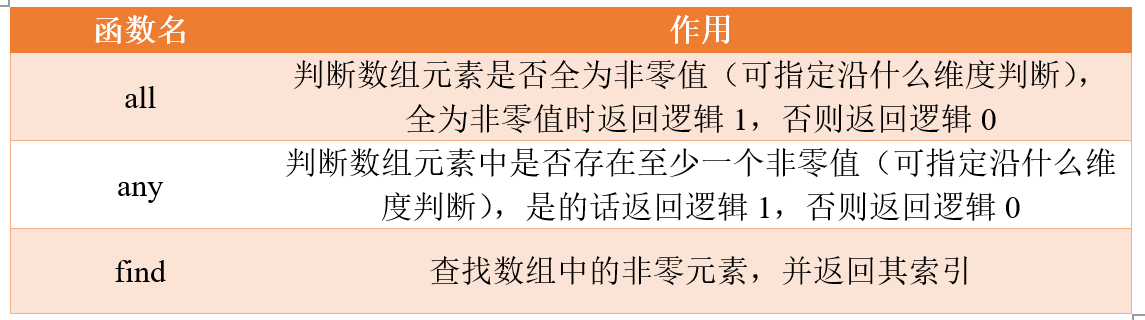

`事实上，`all`函数和`any`函数的用法和我们之前讲解的`sum`函数非常像`

A = randi([-5,5],1,8)

A =     -5     1     4     3    -5    -2     4    -2


all(A)

ans = logical
   1


A = randi([-3,3],3,4)

A =     -3     3    -2    -1
     0    -1     3     1
    -1     3     1     1


all(A)  % all(A,1)

ans = 1×4 logical 数组
   0   1   1   1


all(A,2)

ans = 3×1 logical 数组
   1
   0
   1


`可以看出，`all`函数相当于对向量或者矩阵的元素进行‘逻辑与`&`’运算，只有全为非零值时才返回逻辑值`1`。而`any`函数则相当于对元素进行‘逻辑或`|`’运算，存在至少一个非零值时就会返回逻辑值`1`。`

A = [0 0 0 -1 0 20 0];
any(A)

ans = logical
   1


A = [0 0 0 0 0 0];
any(A)

ans = logical
   0


A = [0  0  -1  2;
    -3  0  1  -2;
    0  0  0  0];
any(A)  % all(A,1)

ans = 1×4 logical 数组
   1   0   1   1


any(A,2)

ans = 3×1 logical 数组
   1
   1
   0


`思考：如果要判断整个矩阵的元素是否全部为非零值应该怎么办？`

`至少两种方法：`all(A(:)) `或者`all(all(A))

A = randi([0,2],2,2)

A = 2×2
     2     0
     0     2


all(A(:))

ans = logical
   0


all(all(A))

ans = logical
   0


`事实上，`all`函数和`any`函数很少直接运用在数值矩阵上，它常常配合逻辑矩阵来实现特定的功能。`

`我们来看下面的练习题：`

`（`1`）请随机生成一个`100`行`3`列的矩阵，用来记录学生的考试成绩：矩阵每一行代表一名同学，每一列代表一门科目的成绩，矩阵中的每个元素都是位于`50`至`100`的整数。`

score = randi([50,100],100,3)

score = 100×3
    75    93    61
    99    76    94
    99    72    95
    85    58    71
    54    80    90
    50    53    64
    58    87    98
    80    55    57
    65    74    66
    53    69    63


`（`2`）三门科目的成绩都不低于`85`分的同学可以获得奖学金评选的资格，请指出哪些同学可以获得资格。要求返回一个包含`100`个元素的逻辑向量，元素为`1`的下标对应的同学有评选资格。`

tmp = all(score >= 85,2) 

tmp = 100×1 logical 数组
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


find(tmp)


ans =

  空的 0×1 double 列向量



find( all(score >= 85,2) )


ans =

  空的 0×1 double 列向量



`（`3`）请指出哪些同学挂科了，至少有一门科目没过`60`就算。要求返回一个包含`100`个元素的逻辑向量，元素为`1`的下标对应的同学挂科了。`

score < 60

ans = 100×3 logical 数组
   0   0   0
   0   0   0
   0   0   0
   0   1   0
   1   0   0
   1   1   0
   1   0   0
   0   1   1
   0   0   0
   1   0   0
   0   0   0
   1   0   0
   0   0   1
   0   0   0
   0   1   0
   0   0   0
   0   0   1
   1   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   1   0   0
   1   0   0
   0   0   0
   0   0   0
   0   1   0
   0   0   0
   0   0   0
   1   0   1
   0   0   1
   0   0   0
   0   0   1
   1   0   0
   1   0   1
   0   0   1
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   1   1   0
   0   1   0
   0   0   0
   0   0   0
   1   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   1
   0   0   0
   0   1   0
   0   0   0
   0   0   1
   0   0   0
   0   0   1
   0   0   0
   0   1   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   1
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   1   0   1
   0   0   0
   0   0   0
   0   0   0
  

any(score < 60,2) 

ans = 100×1 logical 数组
   0
   0
   0
   1
   1
   1
   1
   1
   0
   1
   0
   1
   1
   0
   1
   0
   1
   1
   0
   0
   0
   0
   0
   0
   1
   1
   0
   0
   1
   0
   0
   1
   1
   0
   1
   1
   1
   1
   0
   0
   0
   0
   0
   1
   1
   0
   0
   1
   0
   0
   0
   1
   0
   1
   0
   1
   0
   1
   0
   1
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   1
   0
   0
   1
   0
   0
   1
   1
   0
   1
   1
   1
   0
   0
   1
   1
   1
   0
   1
   0
   0
   1
   0
   0


`（4）这三门科目中是否有科目没有人挂科。要求返回一个包含3个元素的逻辑向量，元素为`1`的下标对应的科目表示没有人挂科。`

score >= 60

ans = 100×3 logical 数组
   1   1   1
   1   1   1
   1   1   1
   1   0   1
   0   1   1
   0   0   1
   0   1   1
   1   0   0
   1   1   1
   0   1   1
   1   1   1
   0   1   1
   1   1   0
   1   1   1
   1   0   1
   1   1   1
   1   1   0
   0   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   0   1   1
   0   1   1
   1   1   1
   1   1   1
   1   0   1
   1   1   1
   1   1   1
   0   1   0
   1   1   0
   1   1   1
   1   1   0
   0   1   1
   0   1   0
   1   1   0
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   0   0   1
   1   0   1
   1   1   1
   1   1   1
   0   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   0
   1   1   1
   1   0   1
   1   1   1
   1   1   0
   1   1   1
   1   1   0
   1   1   1
   1   0   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   0
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   0   1   0
   1   1   1
   1   1   1
   1   1   1
  

all(score >= 60)

ans = 1×3 logical 数组
   0   0   0


`大家应该注意到了，上面问题的答案有一点冗余。例如第二问我们关心的是哪些同学可以获得评选资格，但是答案返回的结果是一个长度为`100`的向量，向量中也包含了没有获得评选资格的同学，它们用逻辑值`0`表示。那么有没有一种方法能够找到这个向量中所有非零元素呢？`find`函数可以帮助我们实现！`

`下面是`MATLAB`官方文档对于`find`函数的介绍：`

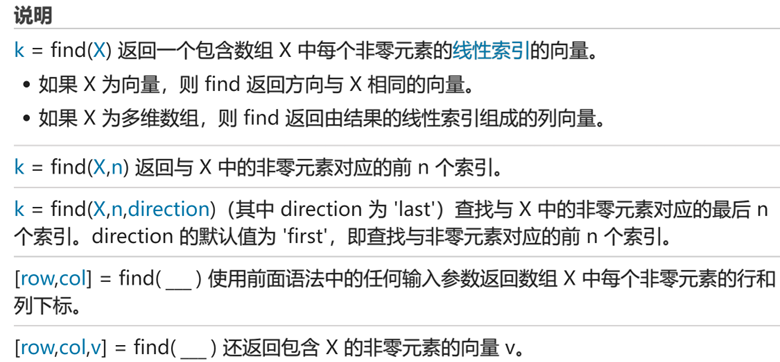

A = [4 0 11 -3 0 2 -4];
ind = find(A)

ind = 1×5
     1     3     4     6     7


[r, c] = find(A)

r = 1×5
     1     1     1     1     1


c = 1×5
     1     3     4     6     7


A = [0 -1 0 0;
     4 0 0 3;
     0 1 0 0];
ind = find(A, 2)

ind = 2×1
     2
     4


ind = find(A, 2, 'last')

ind = 2×1
     6
    11


[row,col] = find(A)

row = 4×1
     2
     1
     3
     2


col = 4×1
     1
     2
     2
     4


[row,col,v] = find(A)

row = 4×1
     2
     1
     3
     2


col = 4×1
     1
     2
     2
     4


v = 4×1
     4
    -1
     1
     3


那么对于我们上面的第二个问题，我们可以使用下面的命令进行改进：

score

score = 100×3
    75    93    61
    99    76    94
    99    72    95
    85    58    71
    54    80    90
    50    53    64
    58    87    98
    80    55    57
    65    74    66
    53    69    63


tmp = all(score >= 85,2);
ind = find(tmp)


ind =

  空的 0×1 double 列向量



`练习题（接着上题来）：`

`（`5`）找出恰好挂了两门科目的同学编号。`

score

score = 100×3
    75    93    61
    99    76    94
    99    72    95
    85    58    71
    54    80    90
    50    53    64
    58    87    98
    80    55    57
    65    74    66
    53    69    63


score < 60

ans = 100×3 logical 数组
   0   0   0
   0   0   0
   0   0   0
   0   1   0
   1   0   0
   1   1   0
   1   0   0
   0   1   1
   0   0   0
   1   0   0
   0   0   0
   1   0   0
   0   0   1
   0   0   0
   0   1   0
   0   0   0
   0   0   1
   1   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   1   0   0
   1   0   0
   0   0   0
   0   0   0
   0   1   0
   0   0   0
   0   0   0
   1   0   1
   0   0   1
   0   0   0
   0   0   1
   1   0   0
   1   0   1
   0   0   1
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   1   1   0
   0   1   0
   0   0   0
   0   0   0
   1   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   1
   0   0   0
   0   1   0
   0   0   0
   0   0   1
   0   0   0
   0   0   1
   0   0   0
   0   1   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   1
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   1   0   1
   0   0   0
   0   0   0
   0   0   0
  

sum(score < 60,2)  % 计算每一行的和

ans = 100×1
     0
     0
     0
     1
     1
     2
     1
     2
     0
     1


tmp = sum(score < 60,2);  % 每位同学挂科的数目
tmp == 2

ans = 100×1 logical 数组
   0
   0
   0
   0
   0
   1
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0


find(tmp == 2)

ans = 7×1
     6
     8
    32
    37
    44
    72
    92


`（`6`）找到总分超过`260`分的同学的编号。`

total_score = sum(score,2); % 计算每位同学的总分
total_score > 260

ans = 100×1 logical 数组
   0
   1
   1
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   1
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   1
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0


find(total_score > 260)

ans = 11×1
     2
     3
    11
    14
    16
    46
    69
    70
    75
    89


配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)